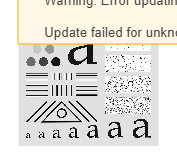

cTP = imread("characterTestPattern.tif");
cTP = im2double(cTP);

FTcTP=fft2(cTP);
FTcTP = fftshift(FTcTP);
A = log(1+ abs(FTcTP));
A = A/max(A(:));



imshow(cTP);

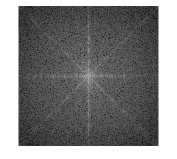

imshow(A);

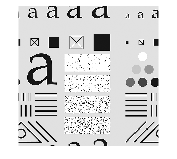


cTP_shift = circshift(cTP,[100, -200]);

FTcTP_shift=fft2(cTP_shift);
FTcTP_shift = fftshift(FTcTP_shift);
B = log(1+ abs(FTcTP_shift));
B = B/max(B(:));

imshow(cTP_shift);

imshow(B);

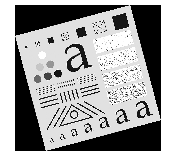


cTP_rot = imrotate(cTP,15,'bicubic');

FTcTP_rot=fft2(cTP_rot);
FTcTP_rot = fftshift(FTcTP_rot);
C = log(1+ abs(FTcTP_rot));
C = C/max(C(:));

imshow(cTP_rot);

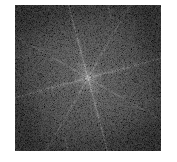

imshow(C);

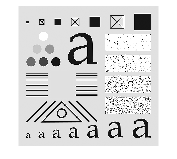

cTP2 = imread("characterTestPattern_2.tif");
cTP2 = im2double(cTP2);

FTcTP2=fft2(cTP2);
FTcTP2 = fftshift(FTcTP2);
D = log(1+ abs(FTcTP2));
D = D/max(D(:));

imshow(cTP2);

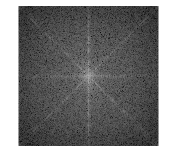

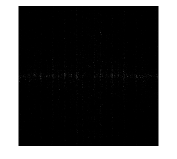

imshow(D);

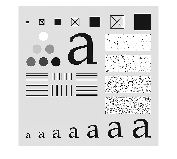

cTP3 = imread("characterTestPattern_3.tif");
cTP3 = im2double(cTP3);

FTcTP3=fft2(cTP3);
FTcTP3 = fftshift(FTcTP3);
E = log(1+ abs(FTcTP3));
E = E/max(E(:));

imshow(cTP3);

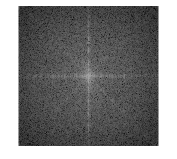

imshow(E);

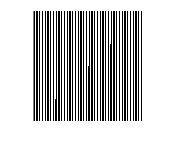

v2 = imread("verticalbars_2.tif");

FTv2 = fft2(v2);
FTv2 = fftshift(FTv2);
F = log(1+abs(FTv2));
F = F/max(F(:));

imshow(v2);

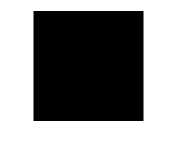

imshow(F);

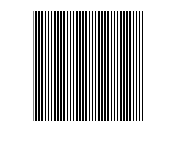

v4 = imread("verticalbars_4.tif");

FTv4 = fft2(v4);
FTv4 = fftshift(FTv4);
G = log(1+abs(FTv4));
G = G/max(G(:));

imshow(v4);

imshow(G);

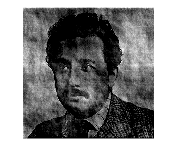

E1 = imread("Einstein1.jpg");
E1 = im2double(E1);

E2 = imread("Einstein2.jpg");
E2 = im2double(E2);

SpecE1 = fft2(E1);
SpecE1 = abs(SpecE1);

SpecE2 = fft2(E2);
SpecE2 = abs(SpecE2);

AnglE1 = fft2(E1);
AnglE1 = angle(AnglE1);

AnglE2 = fft2(E2);
AnglE2 = angle(AnglE2);

E1_E2 = real(ifft2(SpecE1.*exp(1i*AnglE2)));
E2_E1 = real(ifft2(SpecE2.*exp(1i*AnglE1)));
imshow(E1_E2);

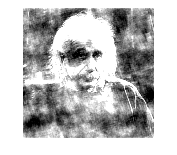

imshow(E2_E1);